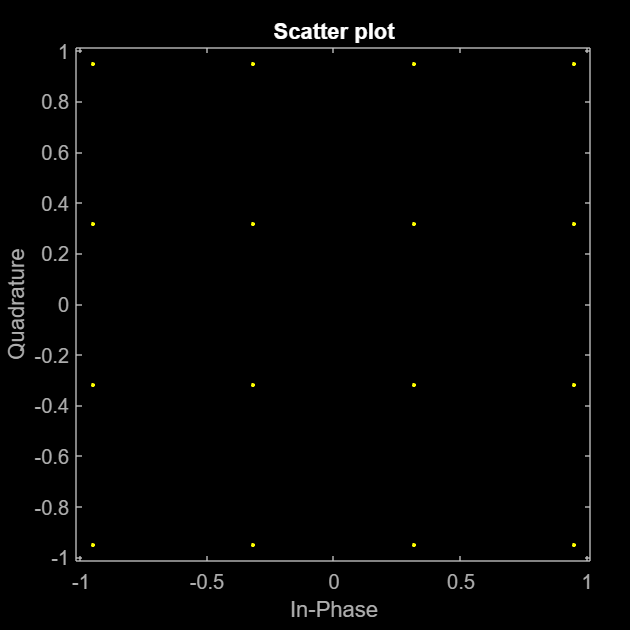


c = 3e8; % speed of light

% OFDM system parameters
subcarrierSpacing = 78.125e3; % subcarrier spacing 
Tu = 1/subcarrierSpacing; % the "useful" symbol period
G = 1/8; % the guard interval fraction
Tg = G*Tu; % the guard interval time
To = Tu + Tg; % the OFDM symbol duration (period)
fC = 5.9e9; %
N = 52; % 48 for data, and 4 pilot tones
numPilotTones = 4; % no. pilot tones used

% QAM
modOrder = 16; % modulation order being used
modType = "QAM"; % type of modulation being used
% https://www.mathworks.com/help/comm/ref/qammod.html
% modulates input signal x by using QAM with the specified modulation order M
modulated = qammod((0:modOrder-1), modOrder, 'UnitAveragePower', true); %create a data vector containing each of the possible symbols
% Display the modulated signal constellation using the scatterplot function.
scatterplot(modulated)